# **ThermoGuard — explaining the CPU model parameters**

Intel Core i5-13600K with a Noctua NH-U12S redux cooler

This document explains the numbers needed for the CPU cooling model. Each section introduces one idea, explains where its numbers come from, and then calculates the result.

Some numbers come from manufacturers. Others are **assumptions**: starting values chosen because the exact information is not available. The calculations keep that difference clear. The detailed calculations and sensitivity studies are saved separately in **cpu_parameter_derivation_detailed.mlx**.

**Reading the code:** a line starting with `%` is a comment. A semicolon `;` stores a value without displaying it. Leaving out the semicolon displays the result. Run the sections from top to bottom using **Run All**.

## 1. What does the model represent?

The CPU produces heat. Heat moves into the heatsink, and the heatsink releases it into the surrounding air. The fan helps the heatsink lose heat faster.

`CPU → heatsink → surrounding air`

We describe the CPU with one temperature and the heatsink with another. This keeps the model simple, although different parts of a real CPU and heatsink can have different temperatures.

There are two main types of parameter:

**Thermal capacitance, C:** how much heat is needed to raise a part's temperature by one degree. A larger value means that it heats up more slowly for the same incoming heat. Its unit is J/K: joules per degree of temperature change.

**Thermal resistance, R:** how difficult it is for heat to move between two places. A larger value means a larger temperature difference is needed to move the same amount of heat. Its unit is K/W: degrees of temperature difference per watt.

For temperature changes, 1 K is the same size as 1 °C. Absolute temperatures are different: 25 °C is 298.15 K.

We use **C_e** for CPU capacitance and **C_h** for heatsink capacitance. **R_eh** is the CPU-to-heatsink resistance. **R_ha** is the heatsink-to-air resistance. The subscripts mean electronics (e), heatsink (h), and air (a).

## 2. CPU power and surrounding temperature

Intel gives 125 W as the processor base power, 181 W as the maximum turbo power, and 100 °C as the maximum junction temperature [1]. Junction temperature means the temperature inside the processor chip.

We use 125 W and 181 W as two test heat loads. Real CPU power changes with the workload. Here, we assume that all of the chosen CPU power becomes heat. We also choose a constant air temperature of 25 °C.

Q_base = 125;       % CPU base heat load [W], Intel
Q_turbo = 181;      % CPU turbo heat load [W], Intel
Tj_max = 100;       % CPU junction temperature limit [degC], Intel
T_a = 25;           % Air entering the cooler [degC], assumed 

The fan's electrical power is separate from the CPU heat load. Noctua gives a maximum fan speed of 1700 rpm [2]. We keep that rating for reference; it does not directly tell us how much heat the cooler removes.

RPM_max = 1700;    % Maximum fan speed [rpm], Noctua

## 3. How much heat can the heatsink store?

Noctua gives a heatsink mass of 550 g without the fan [2]. This is 0.550 kg. The cooler contains aluminium fins and copper in its base and heatpipes.

**Specific heat capacity** tells us how much heat is needed to warm one kilogram of a material by one degree. The reference values used here are 910 J/(kg·K) for aluminium and 390 J/(kg·K) for copper [4]. We use them as approximate constant values.

The calculation is:

`Thermal capacitance = mass × specific heat capacity`

The aluminium/copper mass split is unknown. As a simple starting point, we assume half the mass is aluminium and half is copper. We therefore use the average of their specific heat capacities.

m_heatsink = 0.550;       % Mass without the fan [kg], Noctua
cp_aluminium = 910;      % Specific heat [J/(kg*K)], reference [4]
cp_copper = 390;         % Specific heat [J/(kg*K)], reference [4]

cp_heatsink = (cp_aluminium + cp_copper) / 2;
C_h = m_heatsink * cp_heatsink

C_h = 357.5000

**Result: C_h = 357.5 J/K.** In this model, the heatsink needs 357.5 J of added heat to warm by one degree. The 50/50 material split is an assumption, not a Noctua specification. Small amounts of other materials are left out.

## 4. How much heat can the CPU store?

Intel does not give a thermal capacitance on the specification page used here [1]. We therefore need a starting estimate.

The earlier version used a CPU mass of 35.5 g. That mass could not be verified, so it is kept as an **assumption**. We also use the average specific heat of copper and silicon. The silicon reference value is 710 J/(kg·K) [4].

m_cpu = 0.0355;          % CPU mass [kg], assumed, not verified
cp_silicon = 710;        % Specific heat [J/(kg*K)], reference [4]

cp_cpu = (cp_copper + cp_silicon) / 2;
C_e = m_cpu * cp_cpu

C_e = 19.5250

**Result: C_e = 19.525 J/K.** The CPU has much less estimated heat storage than the heatsink.

The CPU contains more materials than this calculation represents. Also, its chip can heat up before the rest of the package does. Treat C_e as a starting model value; a measured heating response is needed to check it.

## 5. Overall resistance from CPU to air

GamersNexus tested the NH-U12S redux at a 200 W heat load with the fan at full speed. The reported CPU temperature was about 62 °C above the surrounding air [3].

At a steady temperature, we can estimate the overall resistance by dividing the temperature rise by the heat load:

`Overall resistance = temperature rise / heat load`

temperature_rise_test = 62;    % Temperature above air [K], GamersNexus
heat_load_test = 200;          % Test heat load [W], GamersNexus

R_total = temperature_rise_test / heat_load_test

R_total = 0.3100

**Result: R_total = 0.31 K/W.** For example, this resistance would produce a 31-degree rise at a steady 100 W heat load.

**Important assumption:** the published test used an AMD Ryzen 9 3950X, not our Intel CPU. Its result includes the CPU, its connection to the cooler, and the cooler itself. We use 0.31 K/W as a starting estimate for our system. It is not a verified Intel value or a cooler-only property. The same review gives different ratios for its other CPU test setups [3].

## 6. Splitting the resistance into two parts

Our model needs one resistance from the CPU to the heatsink and another from the heatsink to the air:

`R_total = R_eh + R_ha_maxfan`

The published CPU-to-air temperature rise does not tell us how much belongs to each part. For now, we **assume** that 40% belongs to the CPU-to-heatsink path. The other 60% belongs to the heatsink-to-air path at full fan speed.

cpu_resistance_fraction = 0.40;     % Assumed split: 40% and 60%

R_eh = cpu_resistance_fraction * R_total

R_eh = 0.1240

R_ha_maxfan = R_total - R_eh

R_ha_maxfan = 0.1860

**Results: R_eh = 0.124 K/W and R_ha_maxfan = 0.186 K/W.** These add up to 0.31 K/W. The split is a modelling choice, not a measurement.

To check it, we would need CPU, heatsink and air temperatures from the same setup. Subtracting an unrelated Intel case-temperature specification from the AMD benchmark would not give a reliable split.

## 7. How does the fan change cooling?

We choose a heatsink-to-air resistance of 0.50 K/W when the fan is stopped. This is an **assumption**, because the reviewed sources do not provide a stopped-fan resistance for our setup. The heatsink can still lose heat to the surrounding air.

It is convenient to describe fan cooling using **conductance, G**. Conductance is the opposite of resistance: a larger G means heat can escape more easily.

`G = 1 / R`

R_ha_passive = 0.50;           % Stopped-fan resistance [K/W], assumed

G_ha_passive = 1 / R_ha_passive

G_ha_passive = 2

G_ha_maxfan = 1 / R_ha_maxfan

G_ha_maxfan = 5.3763

The results are 2 W/K with the fan stopped and about 5.38 W/K at full cooling.

We use a cooling command **u** between 0 and 1. A value of 0 means a stopped fan, and 1 means full cooling. As a simple approximation, conductance increases in a straight line between those two values.

`G = G_ha_passive + (G_ha_maxfan − G_ha_passive) × u`

The following example calculates the cooling at a halfway command:

u = 0.50;    % Example cooling command; choose a value from 0 to 1

G = G_ha_passive + (G_ha_maxfan - G_ha_passive) * u

G = 3.6882

R_ha = 1 / G

R_ha = 0.2711

**This command is a model input, not a measured fan-speed or electrical PWM percentage.** PWM is the electrical signal used to control the fan. Noctua's PWM guidance describes fan speed, but does not give this heat-removal relationship [5]. In particular, losing the PWM signal is different from stopping the fan: Noctua says that no PWM input produces full speed.

**A simple picture of the assumed fan relationship**

The square brackets below make a short list of cooling commands. The next line calculates G for each command. The remaining lines draw and label the graph.

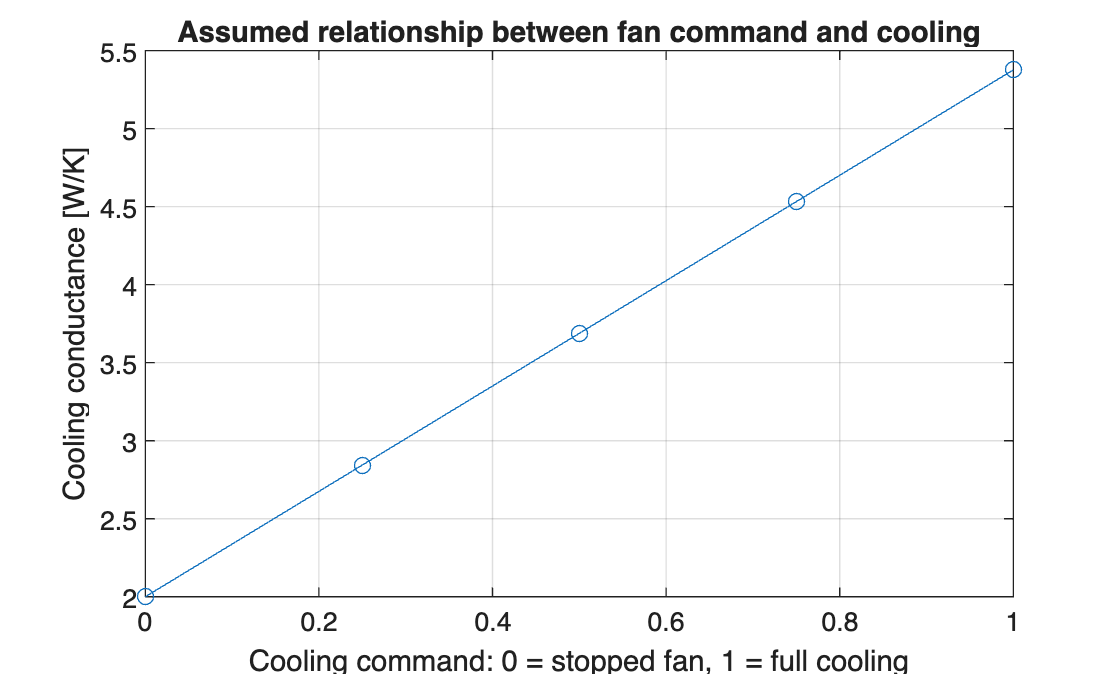

fan_commands = [0 0.25 0.50 0.75 1];
cooling_values = G_ha_passive + (G_ha_maxfan - G_ha_passive) * fan_commands;

figure('Theme','light');
plot(fan_commands, cooling_values, 'o-');
xlabel('Cooling command: 0 = stopped fan, 1 = full cooling');
ylabel('Cooling conductance [W/K]');
title('Assumed relationship between fan command and cooling');
grid on

## 8. Do the chosen resistances give sensible temperatures?

We can check the final temperature the model would approach if the power and fan command stayed constant. This is called the **steady-state temperature**.

`CPU temperature = air temperature + heat load × total resistance`

First, calculate the two full-fan temperatures:

R_fullfan_total = R_eh + R_ha_maxfan;

T_cpu_base_fullfan = T_a + Q_base * R_fullfan_total

T_cpu_base_fullfan = 63.7500

T_cpu_turbo_fullfan = T_a + Q_turbo * R_fullfan_total

T_cpu_turbo_fullfan = 81.1100

**Results: 63.75 °C at 125 W and 81.11 °C at 181 W.** These are predictions from our chosen parameters, not measured Intel temperatures.

Now repeat the calculation with the heatsink still attached but its fan stopped:

R_stoppedfan_total = R_eh + R_ha_passive;

T_cpu_base_stoppedfan = T_a + Q_base * R_stoppedfan_total

T_cpu_base_stoppedfan = 103

T_cpu_turbo_stoppedfan = T_a + Q_turbo * R_stoppedfan_total

T_cpu_turbo_stoppedfan = 137.9440

**Results: 103 °C at 125 W and about 137.94 °C at 181 W.** Both exceed the chosen 100 °C limit. A real CPU can reduce its power or shut down. These calculations keep the heat input constant, so the values above 100 °C only show that the assumed cooling is insufficient at those loads.

For the later controller, the full-fan result also tells us the lowest steady temperature available at each heat load. A fan controller cannot reach a lower temperature unless the cooling system or heat load changes.

## 9. What if the heatsink is removed?

A stopped fan still leaves the heatsink attached. Removing the heatsink is a different situation: the heatsink no longer stores or removes heat from the CPU.

For a simple comparison, assume **no heat escapes from the CPU at all**. All the heat then raises its temperature. The time needed to go from 25 °C to 100 °C is:

`Heating time = CPU capacitance × temperature increase / heat load`

temperature_increase = Tj_max - T_a;

time_to_limit_base = C_e * temperature_increase / Q_base

time_to_limit_base = 11.7150

time_to_limit_turbo = C_e * temperature_increase / Q_turbo

time_to_limit_turbo = 8.0905

**Results: about 11.72 seconds at 125 W and 8.09 seconds at 181 W.** These apply only to this zero-heat-loss calculation and the assumed C_e. They are not measured times for an exposed CPU. A real exposed package still loses some heat, and its chip can heat differently from the whole package.

## 10. Final parameters to use in the model

The table collects the values calculated above. In the code, each list supplies one column. The `table` command places those columns next to each other. The Basis column reminds us which values are specifications and which depend on assumptions.

Parameter = [
    "CPU base heat load"
    "CPU turbo heat load"
    "Air temperature"
    "CPU temperature limit"
    "CPU thermal capacitance"
    "Heatsink thermal capacitance"
    "CPU-to-heatsink resistance"
    "Stopped-fan cooling resistance"
    "Full-fan cooling resistance"
    "Stopped-fan conductance"
    "Full-fan conductance"
];

Value = [
    Q_base
    Q_turbo
    T_a
    Tj_max
    C_e
    C_h
    R_eh
    R_ha_passive
    R_ha_maxfan
    G_ha_passive
    G_ha_maxfan
];

Unit = [
    "W"
    "W"
    "degC"
    "degC"
    "J/K"
    "J/K"
    "K/W"
    "K/W"
    "K/W"
    "W/K"
    "W/K"
];

Basis = [
    "Intel specification [1]"
    "Intel specification [1]"
    "Assumed"
    "Intel specification [1]"
    "Estimated from assumed mass and material values"
    "Noctua mass; assumed material split"
    "Assumed split of a reference test result"
    "Assumed"
    "Assumed split of a reference test result"
    "Calculated from assumed resistance"
    "Calculated from assumed resistance"
];

simscapeParameters = table(Parameter, Value, Unit, Basis)

simscapeParameters = 11×4 table
               Parameter                Value      Unit                           Basis                      
    ________________________________    ______    ______    _________________________________________________

    "CPU base heat load"                   125    "W"       "Intel specification [1]"                        
    "CPU turbo heat load"                  181    "W"       "Intel specification [1]"                        
    "Air temperature"                       25    "degC"    "Assumed"                                        
    "CPU temperature limit"                100    "degC"    "Intel specification [1]"                        
    "CPU thermal capacitance"           19.525    "J/K"     "Estimated from assumed mass and material values"
    "Heatsink thermal capacitance"       357.5    "J/K"     "Noctua mass; assumed material split"            
    "CPU-to-heatsink resistance"         0.124    "K/W"     "Assumed split of a referen

**Entering the values in Simscape**

**Heat storage:** use a Thermal Mass block for each part. Set Mass type to Constant. For the CPU, enter m_cpu as the mass and cp_cpu as the specific heat. For the heatsink, enter m_heatsink and cp_heatsink. The block multiplies these values to obtain C [6].

**Starting temperature:** start both parts and the surrounding air at 25 °C. If a field uses kelvin, enter 298.15 K.

**CPU-to-heatsink path:** enter R_eh in a Thermal Resistance block, with units K/W.

**Heatsink-to-air path:** use a Variable Thermal Resistance block. Feed it the R_ha value calculated from the current cooling command in Section 7, with units K/W [7]. At a stopped-fan condition this must be R_ha_passive; at full cooling it must be R_ha_maxfan. The fixed u = 0.50 above is just an example.

**Heat input:** supply Q_base or Q_turbo in watts to a Controlled Heat Flow Rate Source connected so it adds heat to the CPU. A Temperature Source holds the air node at the chosen air temperature. The physical network also needs a Thermal Reference and Solver Configuration block.

The following assignments keep the variable names used by the detailed version. They only copy the values; they do not perform new calculations. Here, `_sim` means the value is ready to use in Simscape.

Q_base_sim = Q_base;
Q_turbo_sim = Q_turbo;
T_a_sim = T_a;
Tj_max_sim = Tj_max;
C_e_sim = C_e;
C_h_sim = C_h;
R_eh_sim = R_eh;
R_ha_passive_sim = R_ha_passive;
R_ha_maxfan_sim = R_ha_maxfan;
G_ha_passive_sim = G_ha_passive;
G_ha_maxfan_sim = G_ha_maxfan;
RPM_max_sim = RPM_max;

m_e_sim = m_cpu;
cp_e_sim = cp_cpu;
m_h_sim = m_heatsink;
cp_h_sim = cp_heatsink;

T_a_K_sim = T_a + 273.15;
T_e0_K_sim = T_a_K_sim;
T_h0_K_sim = T_a_K_sim;
fan_exponent_sim = 1;          % Straight-line conductance relationship
G_bare_adiabatic_sim = 0;      % Zero heat loss in the no-heatsink comparison

## 11. What have we established?

We now have starting values for the CPU model, with an explanation for each one. The manufacturer power ratings and heatsink mass are sourced. The heat-storage estimates, resistance split and stopped-fan cooling still depend on assumptions.

To improve those assumptions, measure the CPU temperature, heatsink temperature, air temperature and CPU power on the same setup. Watching how the temperatures change after a power or fan change would also help check C_e and C_h.

The detailed version shows how changing the assumed values affects the results. This shorter document explains the main parameter choices and calculations needed to understand that model first.

## Sources

Sources checked on 4 October 2026.

[1] [Intel Core i5-13600K specifications](https://www.intel.com/content/www/us/en/products/sku/230493/intel-core-i513600k-processor-24m-cache-up-to-5-10-ghz/specifications.html). See CPU Specifications for 125 W and 181 W; Package Specifications for the 100 °C junction limit.

[2] [Noctua NH-U12S redux information sheet](https://cdn.noctua.at/media/noctua_nh_u12s_redux_infosheet_en_web.pdf), page 1. Gives 550 g without the fan, aluminium and copper materials, and 1700 rpm maximum fan speed. It does not give the aluminium/copper mass split.

[3] [GamersNexus NH-U12S redux review](https://gamersnexus.net/coolers/50-noctua-air-cooler-review-nh-u12s-redux-vs-stock-amd-coolers-more). See “200W Heat Load at 100% Fan Speed”: approximately 62 degrees above air temperature on a Ryzen 9 3950X. The other full-speed tests give about 58 degrees at 123 W and 38 degrees at 65 W on different CPUs. Those are different test setups, not three measurements of our Intel system.

[4] [Engineering ToolBox — Metals: Specific Heats](https://www.engineeringtoolbox.com/specific-heat-metals-d_152.html). Aluminium, copper and silicon: 0.91, 0.39 and 0.71 kJ/(kg·K). Multiplying by 1000 gives 910, 390 and 710 J/(kg·K).

[5] [Noctua PWM specifications white paper](https://cdn.noctua.at/media/Noctua_PWM_specifications_white_paper.pdf), pages 6–7. Explains the fan-control signal and speed response. It does not give a heat-removal-versus-command relationship.

[6] [MathWorks — Thermal Mass](https://www.mathworks.com/help/simscape/ref/thermalmass.html). Explains mass, specific heat and stored heat. The parameter mapping was also checked against the installed MATLAB R2026a block source.

[7] MathWorks — [Thermal Resistance](https://www.mathworks.com/help/simscape/ref/thermalresistance.html) and [Variable Thermal Resistance](https://www.mathworks.com/help/simscape/ref/variablethermalresistance.html). Resistance is entered in K/W. The variable block takes its resistance through input R; this was also checked against the installed R2026a block source.